x = -1:2/500:1

x =    -1.0000   -0.9960   -0.9920   -0.9880   -0.9840   -0.9800   -0.9760   -0.9720   -0.9680   -0.9640   -0.9600   -0.9560   -0.9520   -0.9480   -0.9440   -0.9400   -0.9360   -0.9320   -0.9280   -0.9240   -0.9200   -0.9160   -0.9120   -0.9080   -0.9040   -0.9000   -0.8960   -0.8920   -0.8880   -0.8840   -0.8800   -0.8760   -0.8720   -0.8680   -0.8640   -0.8600   -0.8560   -0.8520   -0.8480   -0.8440   -0.8400   -0.8360   -0.8320   -0.8280   -0.8240   -0.8200   -0.8160   -0.8120   -0.8080   -0.8040


f = [7.8750, 0, -8.7500 , 0, 1.8750, 0]

f =     7.8750         0   -8.7500         0    1.8750         0


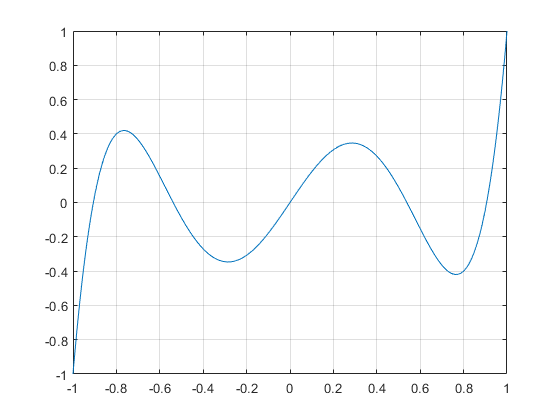

y = polyval(f, x);
plot(x,y)
grid on 


b = sort(roots(f))

b =    -0.9062
   -0.5385
         0
    0.5385
    0.9062


function result = dicho(f, a, b, stop)
    clc;
    close all 
    m = (a + b) / 2;
    fa = polyval(f, a);
    fm = polyval(f, m);
    
    if(abs(a-b) < stop) 
        result = fm;
        return;
    end
    
    if(fa * fm < 0) 
        result = dicho(f, a, m, stop);
        return
    else 
        result = dicho(f, m, b, stop);
        return
        
    end
    
    
end